rootfolder = '../../exp/tartanair_full_semantic/';
use_icp = true

use_icp = logical
   1


gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
hold on

ax1 = cdfplot(error_cvo)

ax1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.2669 0.2669 0.2815 0.2815 0.3794 0.3794 0.3894 0.3894 0.3904 0.3904 0.4024 0.4024 0.4227 0.4227 0.4284 0.4284 0.4392 0.4392 0.4510 0.4510 0.4520 0.4520 0.4673 0.4673 0.4705 0.4705 0.4754 0.4754 0.4823 0.4823 0.4881 0.4881 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 

set( ax1, 'LineWidth', 3,'Color', 'y');

if use_icp==true
    ax2 = cdfplot(error_cvosem)
    set( ax2, 'LineWidth', 3,'Color', 'r');
    ax3 = cdfplot(error_jrmpc)
    set( ax3, 'LineWidth', 3,'Color', 'b');
    
    legend(["RKHS: Intencity only","RKHS: Semantic + Intencity","JRMPC"],'Location','southeast','FontSize', 12)
else
    cdfplot(error_jrmpc)
    legend(["RKHS","JRMPC"],'NumColumns',2,'Location','southwest','FontSize', 12)
end

ax2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.3876 0.3876 0.5276 0.5276 0.5658 0.5658 0.5672 0.5672 0.5734 0.5734 0.5866 0.5866 0.5880 0.5880 0.6088 0.6088 0.6170 0.6170 0.6191 0.6191 0.6348 0.6348 0.6378 0.6378 0.6400 0.6400 0.6524 0.6524 0.6596 0.6596 0.6674 0.6674 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show all propertie

ax3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.2087 0.2087 0.2252 0.2252 0.2307 0.2307 0.2686 0.2686 0.2745 0.2745 0.3073 0.3073 0.3358 0.3358 0.3615 0.3615 0.3828 0.3828 0.3899 0.3899 0.3955 0.3955 0.4135 0.4135 0.4224 0.4224 0.4241 0.4241 0.4330 0.4330 0.4412 0.4412 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show all propertie

xlabel('x', 'FontSize', 18);
ylabel('F(x)', 'FontSize', 18);
gca.YAxis.FontSize = 17

gca = struct with fields:
    YAxis: [1×1 struct]


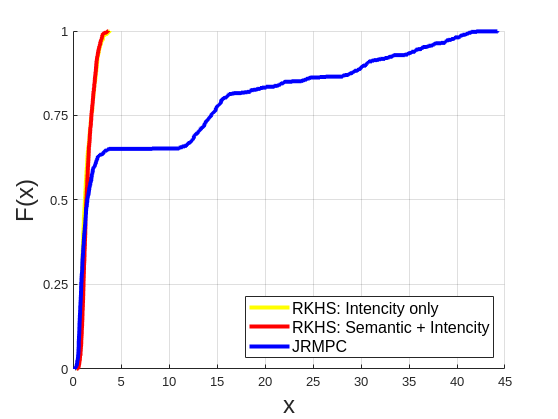

title("")

yticks([0 0.25 0.5 0.75 1])
% title(title_string)
hold off


%% LineStyle

cla
rootfolder = '../../exp/';
use_icp = false

use_icp = logical
   0


gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
hold on

ax1 = cdfplot(error_cvo)

ax1 =   Line (data1) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.5162 0.5162 0.5366 0.5366 0.5490 0.5490 0.5734 0.5734 0.5744 0.5744 0.5816 0.5816 0.6105 0.6105 0.6123 0.6123 0.6311 0.6311 0.6544 0.6544 0.6667 0.6667 0.6921 0.6921 0.6983 0.6983 0.6986 0.6986 0.7125 0.7125 0.7213 0.7213 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show 



if use_icp==true
    cdfplot(error_cvosem)
    cdfplot(error_icp)
    cdfplot(error_jrmpc)
    legend(["RKHS: Intencity only","RKHS: Semantic + Intencity","Colored-ICP","JRMPC"],'Location','southeast')
else
    ax2 = cdfplot(error_jrmpc)
    set( ax1, 'LineWidth', 3,'Color', 'y');
    set( ax2, 'LineWidth', 3,'Color', 'b');
    legend(["RKHS","JRMPC"],'NumColumns',1,'Location','southeast','FontSize', 12)
    
end

ax2 =   Line (JRMPC) with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 0.4231 0.4231 0.5842 0.5842 0.6213 0.6213 0.6330 0.6330 0.6378 0.6378 0.6830 0.6830 0.6890 0.6890 0.6948 0.6948 0.6978 0.6978 0.7091 0.7091 0.7220 0.7220 0.7228 0.7228 0.7268 0.7268 0.7287 0.7287 0.7329 0.7329 0.7371 0.7371 … ]
              YData: [0 0 0.0013 0.0013 0.0025 0.0025 0.0037 0.0037 0.0050 0.0050 0.0063 0.0063 0.0075 0.0075 0.0088 0.0088 0.0100 0.0100 0.0112 0.0112 0.0125 0.0125 0.0138 0.0138 0.0150 0.0150 0.0163 0.0163 0.0175 0.0175 0.0187 0.0187 0.0200 0.0200 … ]

  Show all p

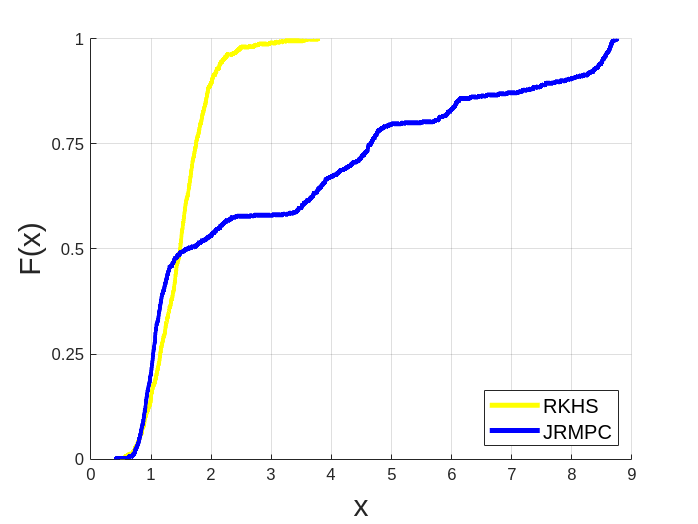

title("")
xlabel('x', 'FontSize', 18);
ylabel('F(x)', 'FontSize', 18);
yticks([0 0.25 0.5 0.75 1])
% title(title_string)
hold off


%% 

## 0.5

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.5.txt');
error_cvo = readmatrix(gtfilename_cvo)

error_cvo =     2.5035
    1.8417
    2.2082
    2.1965
    1.4877
    1.9237
    2.7682
    2.7324
    2.9940
    2.5985


gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.5.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc)

error_jrmpc =     1.3880
    0.9532
   14.9367
   15.8695
   13.2989
    2.0565
    1.4807
    2.5780
    1.0722
    2.3957


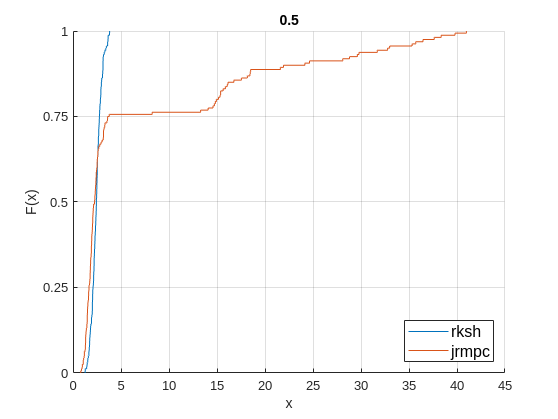

hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"],'Location','southeast')
title("0.5")
hold off

## 0.0

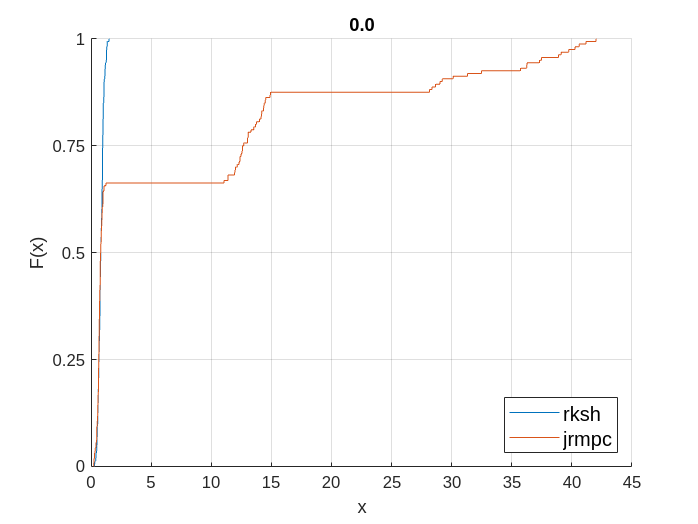

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.0.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.0.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"])
title("0.0")
hold off

## 0.125

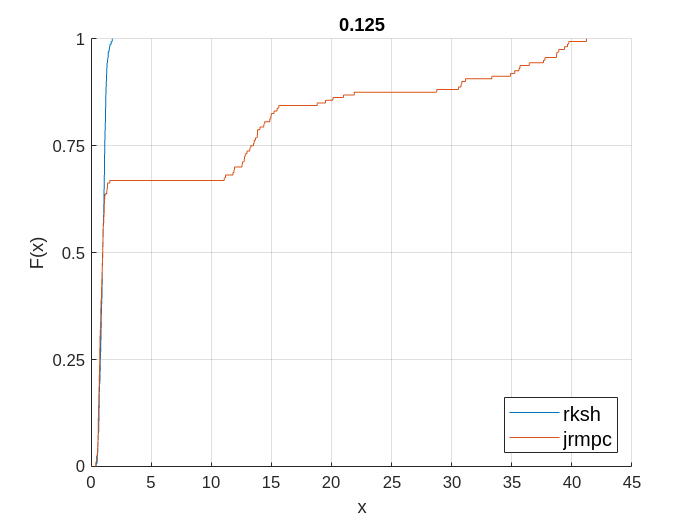

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.125.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.125.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
title("0.125")
legend(["rksh","jrmpc"])
hold off